**DATA ANALYSIS USING INTER AND INTRA VARAINCE **

clc, clearvars, close all;

filePath = 'CW-Data';

%Intialize a table to store variances of each user 
userRow = {'User1','User2','User3','User4','User5','User6','User7','User8','User9','User10'};
fileColumn = {'Acc_FreqD_FDay','Acc_FreqD-MDay','Acc_TimeD_FDay','Acc_TimeD_FreqD_FDay','Acc_TimeD_FreqD_MDay','Acc_TimeD_MDay'};

intraVarianceTableOfUsers = array2table(zeros(10,6),'VariableNames',fileColumn,'RowNames',userRow);

NumUsers = 10;
filesPerUser = 6;

for numUser = 1:NumUsers

    if numUser == 10
        filePattern = fullfile(filePath,sprintf('U%d*.mat',numUser));
    else
        filePattern = fullfile(filePath,sprintf('U0%d*.mat',numUser));
    end

    userFiles = dir(filePattern);

    for file = 1:filesPerUser

        fileData = load(userFiles(file).name);
        varName = fieldnames(fileData);

        data = fileData.(varName{1});
        featureVariance = var(data,0,1);
        meanVariance = mean(featureVariance);

        intraVarianceTableOfUsers{numUser,file} = meanVariance;
    end
end

disp(intraVarianceTableOfUsers);

              Acc_FreqD_FDay    Acc_FreqD-MDay    Acc_TimeD_FDay    Acc_TimeD_FreqD_FDay    Acc_TimeD_FreqD_MDay    Acc_TimeD_MDay
              ______________    ______________    ______________    ____________________    ____________________    ______________

    User1       0.00041201        0.00037531            40.6               27.273                  27.575               41.049    
    User2       0.00080403        0.00077879          29.135               19.572                  13.487               20.077    
    User3       0.00026874         0.0003693          43.512               29.229                  9.3276               13.885    
    User4       0.00051327        0.00047591          21.957            



%Average Intra User variance
intraUserMeanVariances = mean(table2array(intraVarianceTableOfUsers),2); % getting the mean of all the variance values of 6 files per user 
averageIntraUserMeanVariance = mean(intraUserMeanVariances); %Getting the mean of the variances of all the 10 users

meanVariancePerUser = table(userRow', intraUserMeanVariances, 'VariableNames', {'User', 'IntraUserMeanVariance'});
disp(meanVariancePerUser);

       User       IntraUserMeanVariance
    __________    _____________________

    {'User1' }            22.75        
    {'User2' }           13.712        
    {'User3' }           15.992        
    {'User4' }           15.957        
    {'User5' }           21.315        
    {'User6' }           32.355        
    {'User7' }           11.636        
    {'User8' }           20.994        
    {'User9' }           23.715        
    {'User10'}           21.799        



disp(['Average Intra User Variance: ',num2str(averageIntraUserMeanVariance)]);

Average Intra User Variance: 20.0225




%Inter User variance
interUserVariance = var(intraUserMeanVariances); %calculate the inter user variance of the 10 users
disp(['Inter User Variance: ',num2str(interUserVariance)]);

Inter User Variance: 35.7628




%Ratio
varinaceRatio = interUserVariance/averageIntraUserMeanVariance; %Getting the Ratio of interUserVaraince/avg.Intra user variance
disp(['Ratio (Inter-User Variance / Average-Intra user variance): ',num2str(varinaceRatio)]);

Ratio (Inter-User Variance / Average-Intra user variance): 1.7861


**VISUALIZATION OF THE INTRA USER VARIANCE**

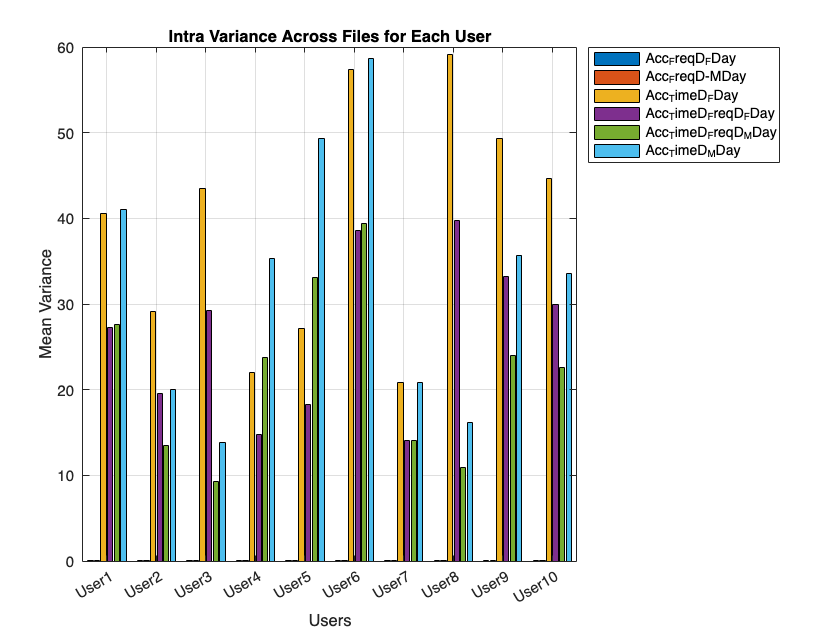

meanIntraVarianceData = table2array(intraVarianceTableOfUsers);

% Create a grouped bar chart
figure;
bar(meanIntraVarianceData, 'grouped');

%Creating the Users
xticks(1:10); 
xticklabels(intraVarianceTableOfUsers.Properties.RowNames);  % Use row names as labels

legend(intraVarianceTableOfUsers.Properties.VariableNames, 'Location', 'northeastoutside');
title('Intra Variance Across Files for Each User');
xlabel('Users');
ylabel('Mean Variance');
grid on;

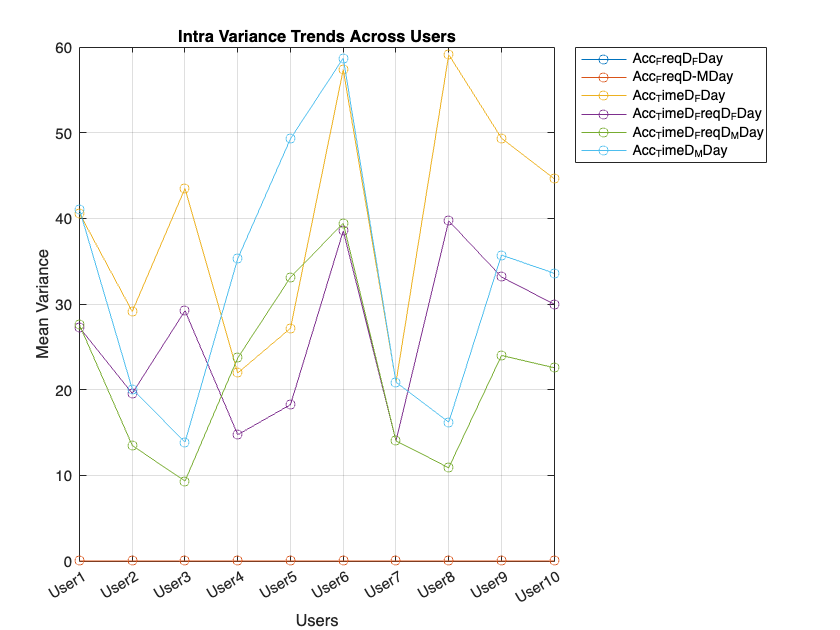



% Plot each file as a separate line
figure;
plot(meanIntraVarianceData, '-o');

% Add legend and labels
legend(intraVarianceTableOfUsers.Properties.VariableNames, 'Location', 'northeastoutside');
title('Intra Variance Trends Across Users');
xlabel('Users');
ylabel('Mean Variance');

xticks(1:10); 
xticklabels(intraVarianceTableOfUsers.Properties.RowNames);
grid on;